figure

img = rgb2gray(imread("grad.png"))

img = 8×8 uint8 matrix
     0   255   255   255   255   255   255   255
     0     0   255   255   255   255   255   255
     0     0     0   255   255   255   255   255
     0     0     0     0   255   255   255   255
     0     0     0     0     0   255   255   255
     0     0     0     0     0     0   255   255
     0     0     0     0     0     0     0   255
     0     0     0     0     0     0     0     0


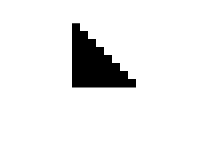

imshow(img, 'InitialMagnification', 1000);

Gx = imfilter(double(img), [-1, 0, 1], 'replicate')

Gx =    255   255     0     0     0     0     0     0
     0   255   255     0     0     0     0     0
     0     0   255   255     0     0     0     0
     0     0     0   255   255     0     0     0
     0     0     0     0   255   255     0     0
     0     0     0     0     0   255   255     0
     0     0     0     0     0     0   255   255
     0     0     0     0     0     0     0     0


Gy = imfilter(double(img), [-1, 0, 1]', 'replicate')

Gy =      0  -255     0     0     0     0     0     0
     0  -255  -255     0     0     0     0     0
     0     0  -255  -255     0     0     0     0
     0     0     0  -255  -255     0     0     0
     0     0     0     0  -255  -255     0     0
     0     0     0     0     0  -255  -255     0
     0     0     0     0     0     0  -255  -255
     0     0     0     0     0     0     0  -255


Gp = sqrt(Gx.*Gx + Gy.*Gy)

Gp =   255.0000  360.6245         0         0         0         0         0         0
         0  360.6245  360.6245         0         0         0         0         0
         0         0  360.6245  360.6245         0         0         0         0
         0         0         0  360.6245  360.6245         0         0         0
         0         0         0         0  360.6245  360.6245         0         0
         0         0         0         0         0  360.6245  360.6245         0
         0         0         0         0         0         0  360.6245  360.6245
         0         0         0         0         0         0         0  255.0000


Ga = rad2deg(atan2(Gy, Gx))

Ga =      0   -45     0     0     0     0     0     0
     0   -45   -45     0     0     0     0     0
     0     0   -45   -45     0     0     0     0
     0     0     0   -45   -45     0     0     0
     0     0     0     0   -45   -45     0     0
     0     0     0     0     0   -45   -45     0
     0     0     0     0     0     0   -45   -45
     0     0     0     0     0     0     0   -90


Ga(Ga < 0) = Ga(Ga < 0) + 180;
Ga(Ga == 180) = 0

Ga =      0   135     0     0     0     0     0     0
     0   135   135     0     0     0     0     0
     0     0   135   135     0     0     0     0
     0     0     0   135   135     0     0     0
     0     0     0     0   135   135     0     0
     0     0     0     0     0   135   135     0
     0     0     0     0     0     0   135   135
     0     0     0     0     0     0     0    90


Gd = round(Ga / 20);
Gd(Gd == 9) = 0

Gd =      0     7     0     0     0     0     0     0
     0     7     7     0     0     0     0     0
     0     0     7     7     0     0     0     0
     0     0     0     7     7     0     0     0
     0     0     0     0     7     7     0     0
     0     0     0     0     0     7     7     0
     0     0     0     0     0     0     7     7
     0     0     0     0     0     0     0     5


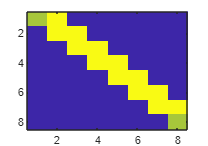

imagesc(Gp)

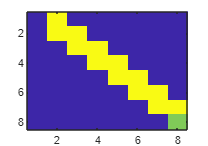

imagesc(Ga)

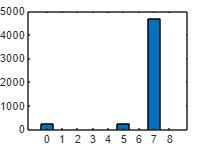

ids = 0:8;
sums = zeros(1, 9);
for i=ids
    sums(i+1) = sum(Gp(Gd == i));
end

bar(ids, sums)

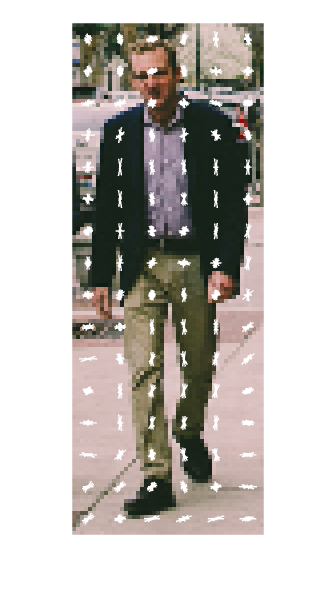

figure;
I1 = imread("person_1.jpg");
[hog1,vis1] = extractHOGFeatures(I1);
imshow(I1, 'InitialMagnification', 500); 
hold on;
plot(vis1);

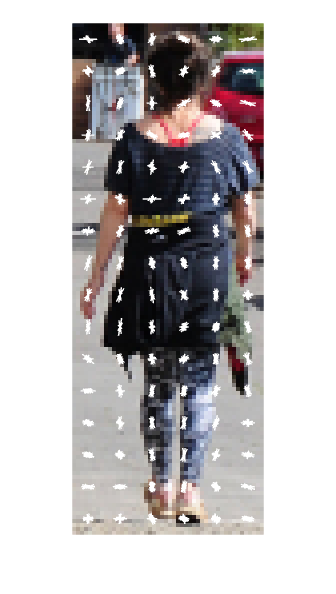

figure;
I2 = imread("person_2.jpg");
[hog2,vis2] = extractHOGFeatures(I2);
imshow(I2, 'InitialMagnification', 500); 
hold on;
plot(vis2);

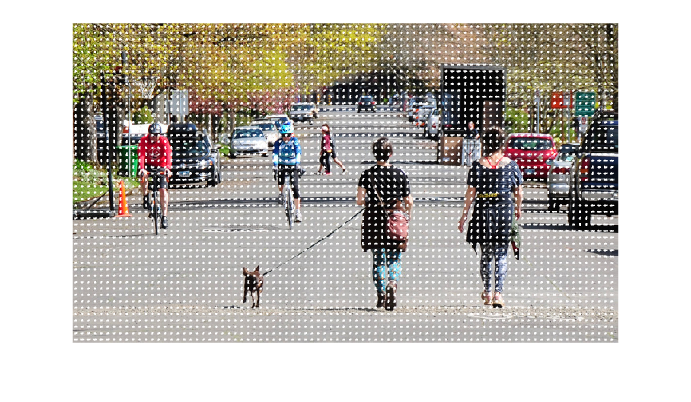

figure;
load('model.mat')
load('gTruth.mat')
It = imread("people_1.jpg");
imshow(It);
hold on
[hogt,vist] = extractHOGFeatures(It);
plot(vist)

scale = 1

count_x = 77

count_y = 34

best_score = 1.6781

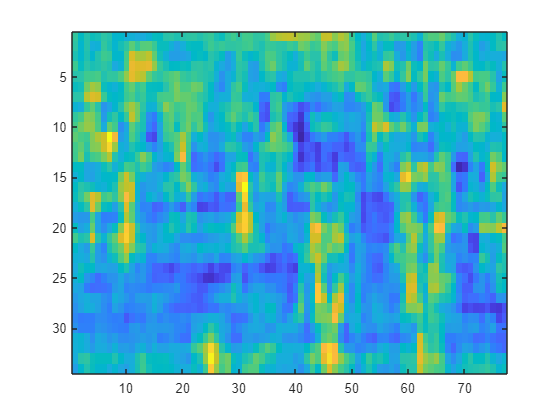

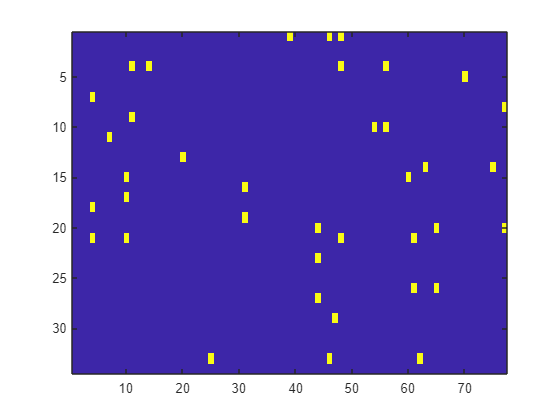

scale = 0.8000

count_x = 60

count_y = 24

best_score = 1.9233

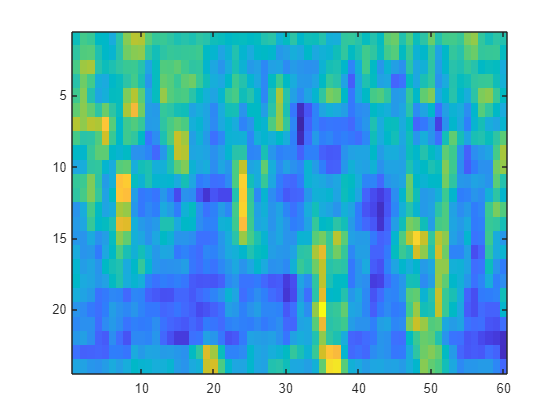

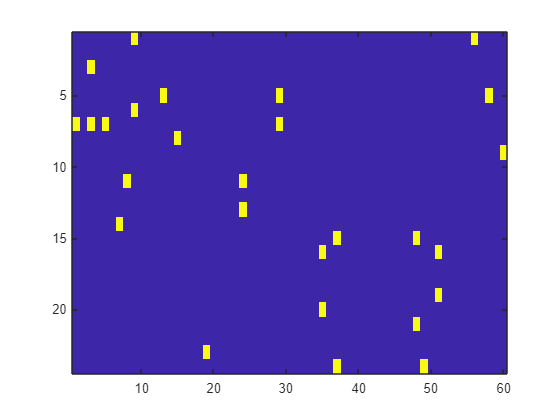

scale = 0.6400

count_x = 46

count_y = 16

best_score = 2.2756

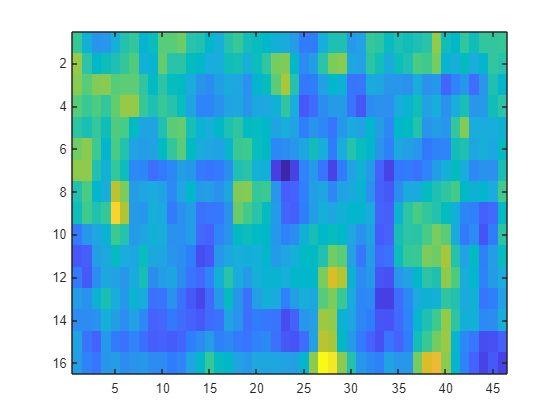

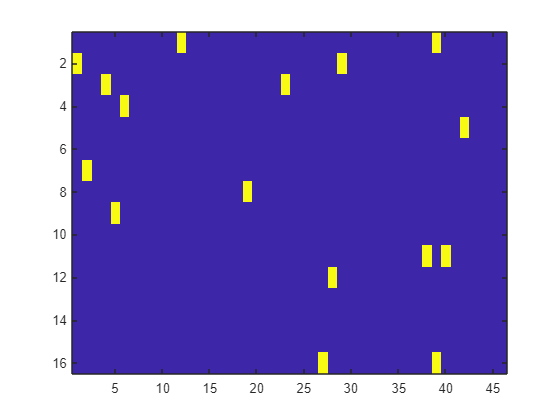

scale = 0.5120

count_x = 35

count_y = 9

best_score = 1.7438

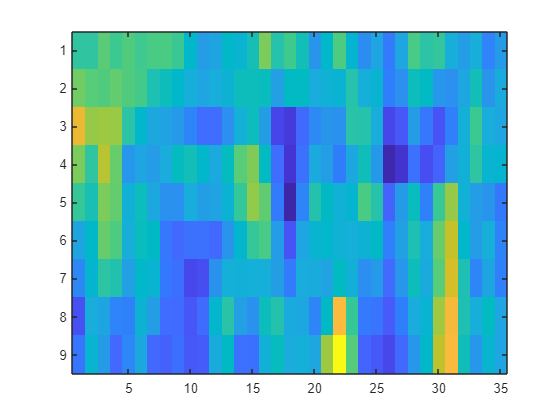

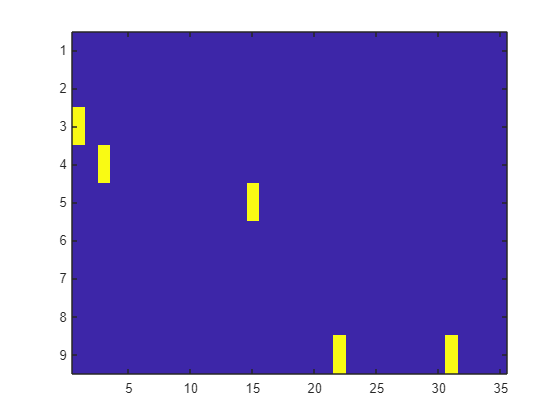

scale = 0.4096

count_x = 27

count_y = 4

best_score = 0.6601

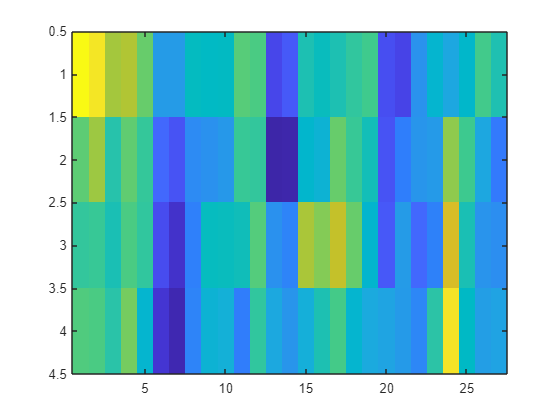

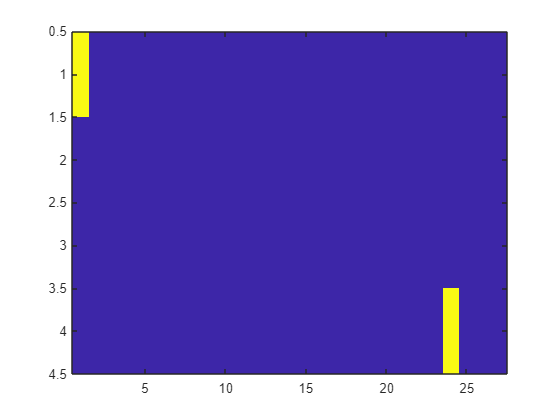

sx = 64;
sy = 128;
step = 8;

scale_step = 0.8;
levels = 5;
thr = 0;

scale = 1.0;

dets = [];
scores = [];
labels = {};

for k=1:levels

scale
cur_img = imresize(It, scale);

w = size(cur_img, 2);
h = size(cur_img, 1);

count_x = floor((w - sx) / step)
count_y = floor((h - sy) / step)

out = zeros(count_y, count_x);

for j=0:count_y-1
    for i=0:count_x-1
        x = 1+(i*step);
        y = 1+(j*step);
        sub_img = cur_img(y:y+sy, x:x+sx);
        sub_hog = extractHOGFeatures(sub_img);
        % klasyfikator
        % dist = min(sum((sub_hog - hog1) .^ 2 ), sum((sub_hog - hog2) .^ 2 ));
        
        [prediction, ~, posterior] = predict(model, sub_hog, 'Posterior', true);
        dist = posterior;
        out(j+1, i+1) = dist;
    end
end

best_score = max(max(out))

figure;
imagesc(out)
figure;
maxes = imregionalmax(out);
maxes(out < thr) = 0;
imagesc(maxes);
[rs, cs] = find(maxes);

for i=1:size(rs)
    x = ((cs(i)-1) * step) / scale + 1;
    y = ((rs(i)-1) * step) / scale + 1;
    w = sx / scale;
    h = sy / scale;
    
    dets = [dets; [x,y,w,h] ];
    scores = [scores, out(rs(i), cs(i))];
    labels{size(dets, 1)} = num2str(out(rs(i), cs(i)), '%.1f');
end

scale = scale * scale_step;

end

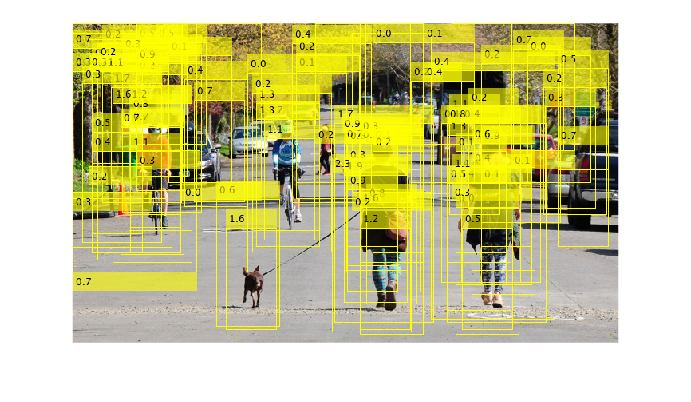

imshow(insertObjectAnnotation(It, 'rectangle', dets, labels));

### Filtracja detekcji i NMS

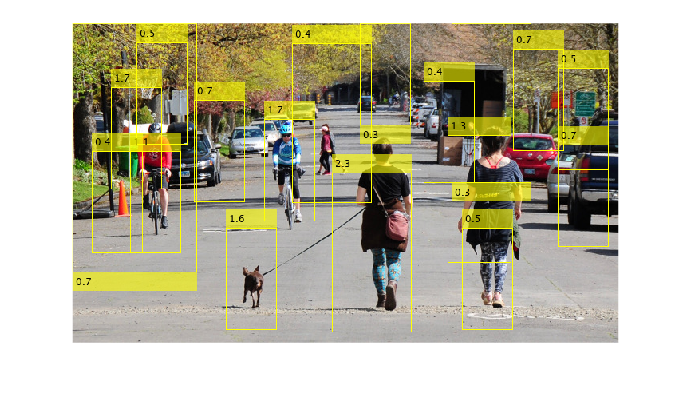

filtered_dets = [];
filtered_scores = [];
tmp_dets = dets;
tmp_scores = scores;
while 1
    [m, i] = max(tmp_scores);
    filtered_dets = [filtered_dets; tmp_dets(i,:)];
    filtered_scores = [filtered_scores, m];
    ratio = bboxOverlapRatio(tmp_dets(i, :), tmp_dets);
    tmp_dets = tmp_dets(ratio < 0.2, :);
    tmp_scores = tmp_scores(ratio < 0.2);
    if size(tmp_dets, 1) < 1
        break
    end
end
cnt = size(filtered_scores, 2);
filtered_lbls = cell(cnt, 1);
for i=1:cnt
    filtered_lbls{i} = num2str(filtered_scores(i), '%.1f');
end
imshow(insertObjectAnnotation(It, "rectangle", filtered_dets, filtered_lbls));

gt_rect=gTruth.LabelData.person{1,1};

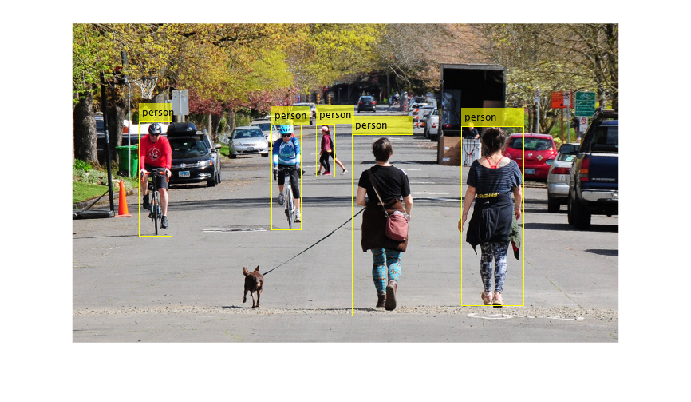

ann1 = insertObjectAnnotation(It, "rectangle", gt_rect, "person");
imshow(ann1);

score_thr = 1.0;
selected_dets = filtered_dets(filtered_scores > score_thr, :);
selected_scores = filtered_scores(filtered_scores > score_thr);
ratio = bboxOverlapRatio(gt_rect, selected_dets)

ratio =          0         0    0.2093         0         0    0.4611
         0    0.5340         0    0.0016         0         0
    0.0010         0         0         0         0         0
    0.5588         0         0         0         0         0
         0         0         0         0    0.4918         0


[best_overlaps, good_ids] = max(ratio, [], 2)

best_overlaps =     0.4611
    0.5340
    0.0010
    0.5588
    0.4918


good_ids =      6
     2
     1
     1
     5


iou = 0.4;
best_ids = good_ids(best_overlaps > iou)

best_ids =      6
     2
     1
     5


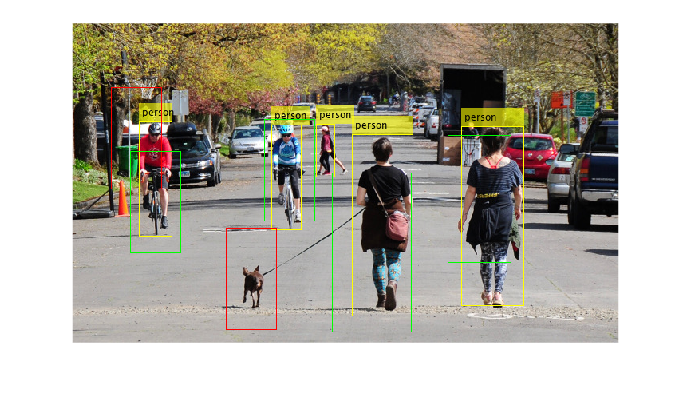

pos_neg = zeros(size(selected_dets, 1), 1);
pos_neg(best_ids) = 1;
tp_boxes = selected_dets(pos_neg==1, :);
fp_boxes = selected_dets(pos_neg==0, :);
ann2 = insertObjectAnnotation(ann1, "rectangle", fp_boxes, "", "Color", 'red');
ann2 = insertObjectAnnotation(ann2, "rectangle", tp_boxes, "", "Color", 'green');
imshow(ann2)

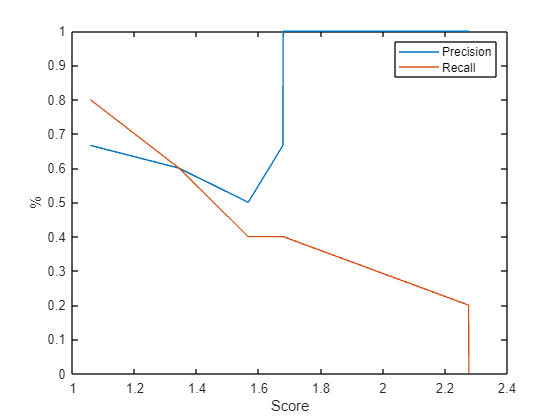

[P, R, sc] = calcpr(selected_dets, selected_scores, gt_rect, iou);
figure;
plot(sc, P);
hold on
plot(sc, R);
legend(["Precision", "Recall"]);
xlabel("Score");
ylabel("%");

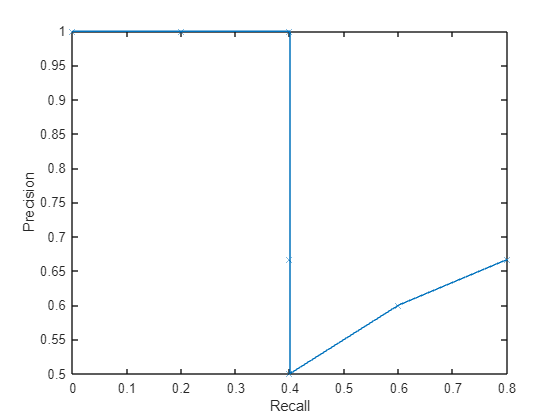

figure;
plot(R, P, 'x-');
xlabel("Recall");
ylabel("Precision");

ap = trapz(flip(R), flip(P))

ap = 0.6367

## Dla reszty obrazów testowych

images=4;

selected_dets_cell = {selected_dets};
selected_scores_cell = {selected_scores};
gt_rect_cell = {gt_rect};

img_i = 2

scale = 1

scale = 0.8000

scale = 0.6400

scale = 0.5120

scale = 0.4096

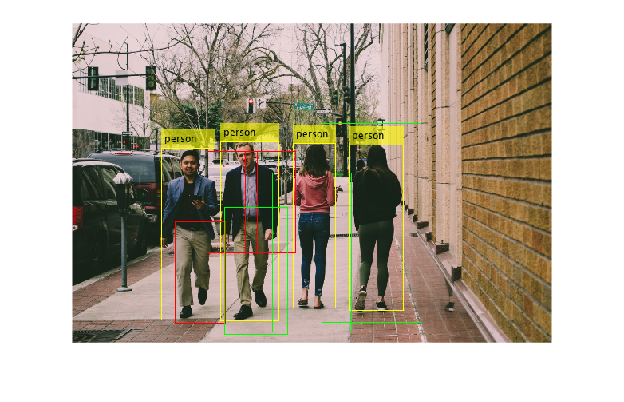

img_i = 3

scale = 1

scale = 0.8000

scale = 0.6400

scale = 0.5120

scale = 0.4096

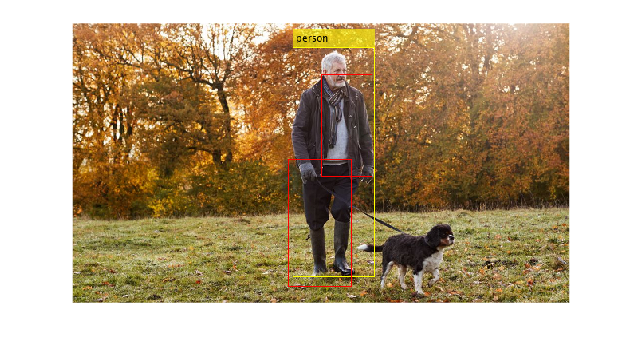

img_i = 4

scale = 1

scale = 0.8000

scale = 0.6400

scale = 0.5120

scale = 0.4096

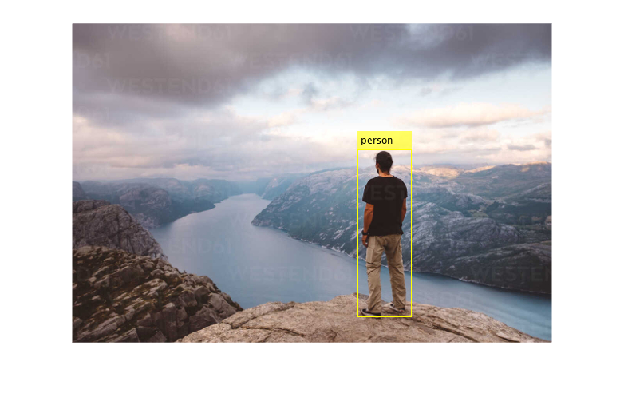


for img_i=2:images
img_i

It = imread(sprintf("people_%d.jpg", img_i));
scale = 1;

dets = [];
scores = [];
labels = {};

for k=1:levels

scale
cur_img = imresize(It, scale);

w = size(cur_img, 2);
h = size(cur_img, 1);

count_x = floor((w - sx) / step);
count_y = floor((h - sy) / step);

out = zeros(count_y, count_x);

for j=0:count_y-1
    for i=0:count_x-1
        x = 1+(i*step);
        y = 1+(j*step);
        sub_img = cur_img(y:y+sy, x:x+sx);
        sub_hog = extractHOGFeatures(sub_img);
        % klasyfikator
        % dist = min(sum((sub_hog - hog1) .^ 2 ), sum((sub_hog - hog2) .^ 2 ));
        
        [prediction, ~, posterior] = predict(model, sub_hog, 'Posterior', true);
        dist = posterior;
        out(j+1, i+1) = dist;
    end
end

maxes = imregionalmax(out);
maxes(out < thr) = 0;
[rs, cs] = find(maxes);

for i=1:size(rs)
    x = ((cs(i)-1) * step) / scale + 1;
    y = ((rs(i)-1) * step) / scale + 1;
    w = sx / scale;
    h = sy / scale;
    
    dets = [dets; [x,y,w,h] ];
    scores = [scores, out(rs(i), cs(i))];
    labels{size(dets, 1)} = num2str(out(rs(i), cs(i)), '%.1f');
end

scale = scale * scale_step;

end

filtered_dets = [];
filtered_scores = [];
tmp_dets = dets;
tmp_scores = scores;
while 1
    [m, i] = max(tmp_scores);
    filtered_dets = [filtered_dets; tmp_dets(i,:)];
    filtered_scores = [filtered_scores, m];
    ratio = bboxOverlapRatio(tmp_dets(i, :), tmp_dets);
    tmp_dets = tmp_dets(ratio < 0.2, :);
    tmp_scores = tmp_scores(ratio < 0.2);
    if size(tmp_dets, 1) < 1
        break
    end
end


gt_rect=gTruth.LabelData.person{img_i,1};
ann1 = insertObjectAnnotation(It, "rectangle", gt_rect, "person");

score_thr = 1.0;
selected_dets = filtered_dets(filtered_scores > score_thr, :);
selected_scores = filtered_scores(filtered_scores > score_thr);
ratio = bboxOverlapRatio(gt_rect, selected_dets);

[best_overlaps, good_ids] = max(ratio, [], 2);
iou = 0.4;
best_ids = good_ids(best_overlaps > iou);

pos_neg = zeros(size(selected_dets, 1), 1);
pos_neg(best_ids) = 1;
tp_boxes = selected_dets(pos_neg==1, :);
fp_boxes = selected_dets(pos_neg==0, :);
ann2 = insertObjectAnnotation(ann1, "rectangle", fp_boxes, "", "Color", 'red');
ann2 = insertObjectAnnotation(ann2, "rectangle", tp_boxes, "", "Color", 'green');
figure;
imshow(ann2)

gt_rect_cell{img_i} = gt_rect;
selected_dets_cell{img_i} = selected_dets;
selected_scores_cell{img_i} = selected_scores;

end

[P, R, sc] = calcprmulti(selected_dets_cell, selected_scores_cell, gt_rect_cell, iou);

sc =     1.0566    1.0981    1.1212    1.3426    1.5653    1.6319    1.6773    1.6781    1.6833    2.2756    2.4855    2.5342    2.5917    2.9525    2.9535


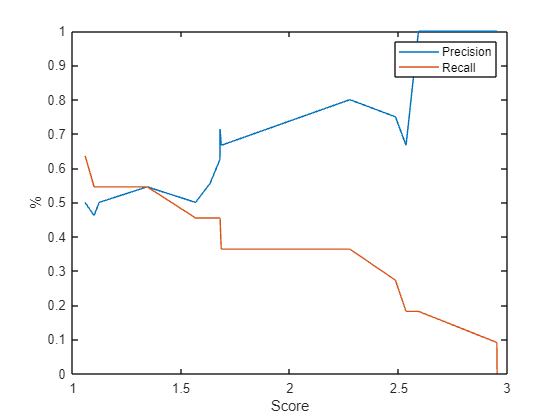

figure;
plot(sc, P);
hold on
plot(sc, R);
legend(["Precision", "Recall"]);
xlabel("Score");
ylabel("%");

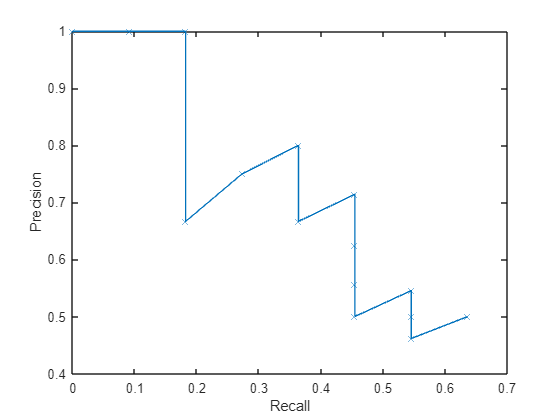

figure;
plot(R, P, 'x-');
xlabel("Recall");
ylabel("Precision");

ap = trapz(flip(R), flip(P))

ap = 0.4707

    all_scores = [];
    all_score_idx = [];
    for ii=1:size(selected_scores_cell, 2)
        all_scores = [all_scores, selected_scores_cell{ii}];
        all_score_idx = [all_score_idx, zeros(1, size(selected_scores_cell{ii}, 2)) + ii];
    end


function [P, R, sc] = calcpr(dets, scores, gt_rect, iou)
    cnt = size(scores, 2) + 1;
    P = zeros(cnt, 1);
    R = zeros(cnt, 1);
    sorted_scores = sort(scores);
    
    sorted_scores = [sorted_scores, max(scores)+0.001];
    sc = sorted_scores;

    P(cnt) = 1;
    R(cnt) = 0;
    
    all_pos = size(gt_rect, 1);
    
    for ii=1:cnt-1
        score_thr = sorted_scores(ii);
        selected_dets = dets(scores >= score_thr, :);
        ratio = bboxOverlapRatio(gt_rect, selected_dets);
        [best_overlaps, good_ids] = max(ratio, [], 2);
        best_ids = good_ids(best_overlaps > iou);
        tp = size(best_ids, 1);
        fn = all_pos - tp;
        fp = size(selected_dets, 1) - tp;
        P(ii) = tp / (tp + fp);
        R(ii) = tp / (tp + fn);
    end
end

function [P, R, sc] = calcprmulti(dets, scores, gt_rect, iou)
    all_scores = [];
    all_score_idx = [];
    for ii=1:size(scores, 2)
        all_scores = [all_scores, scores{ii}];
        all_score_idx = [all_score_idx, zeros(1, size(scores{ii}, 2)) + ii];
    end
    [sorted_scores, sorted_idx] = sort(all_scores);
    sorted_score_idx = all_score_idx(sorted_idx);
    sc = sorted_scores;
    
    P = [];
    R = [];
    
    for ii=1:size(sorted_scores, 2)
        score_thr = sorted_scores(ii);
        idx = sorted_score_idx(ii);

        tp = 0;
        fn = 0;
        fp = 0;

        for jj=1:size(scores, 2)
            dets_cell = dets{jj};
            gt_rect_cell = gt_rect{jj};
            scores_cell = scores{jj};
            all_pos = size(gt_rect_cell, 1);

            selected_dets = dets_cell(scores_cell >= score_thr, :);
            if (size(selected_dets, 1) == 0)
                tp_d = 0;
                fn_d = all_pos;
                fp_d = 0;
            else
                ratio = bboxOverlapRatio(gt_rect_cell, selected_dets);
                [best_overlaps, good_ids] = max(ratio, [], 2);
                best_ids = good_ids(best_overlaps > iou);
                tp_d = size(best_ids, 1);
                fn_d = all_pos - tp_d;
                fp_d = size(selected_dets, 1) - tp_d;
            end
            tp = tp + tp_d;
            fn = fn + fn_d;
            fp = fp + fp_d;
        end

        P = [P; tp / (tp + fp)];
        R = [R; tp / (tp + fn)];
    end

    sc = [sc, max(sorted_scores) + 0.001];
    P = [P; 1];
    R = [R; 0];
end